# Machine Learning Online Class - Exercise 1: Linear Regression

%  Instructions
%  ------------
% 
%  This file contains code that helps you get started on the
%  linear exercise. You will need to complete the following functions 
%  in this exericse:
%
%     warmUpExercise.m
%     plotData.m
%     gradientDescent.m
%     computeCost.m
%     gradientDescentMulti.m
%     computeCostMulti.m
%     featureNormalize.m
%     normalEqn.m
%
%  For this exercise, you will not need to change any code in this file,
%  or any other files other than those mentioned above.
%
% x refers to the population size in 10,000s
% y refers to the profit in $10,000s
%

## Initialization

clear ; close all; clc

## ==================== Part 1: Basic Function ====================

Complete warmUpExercise.m 

fprintf('Running warmUpExercise ... \n');

Running warmUpExercise ... 


fprintf('5x5 Identity Matrix: \n');

5x5 Identity Matrix: 


warmUpExercise()

ans =      8     8     8     8     8
     8     8     8     8     8
     8     8     8     8     8
     8     8     8     8     8
     8     8     8     8     8



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ======================= Part 2: Plotting =======================

fprintf('Plotting Data ...\n')

Plotting Data ...


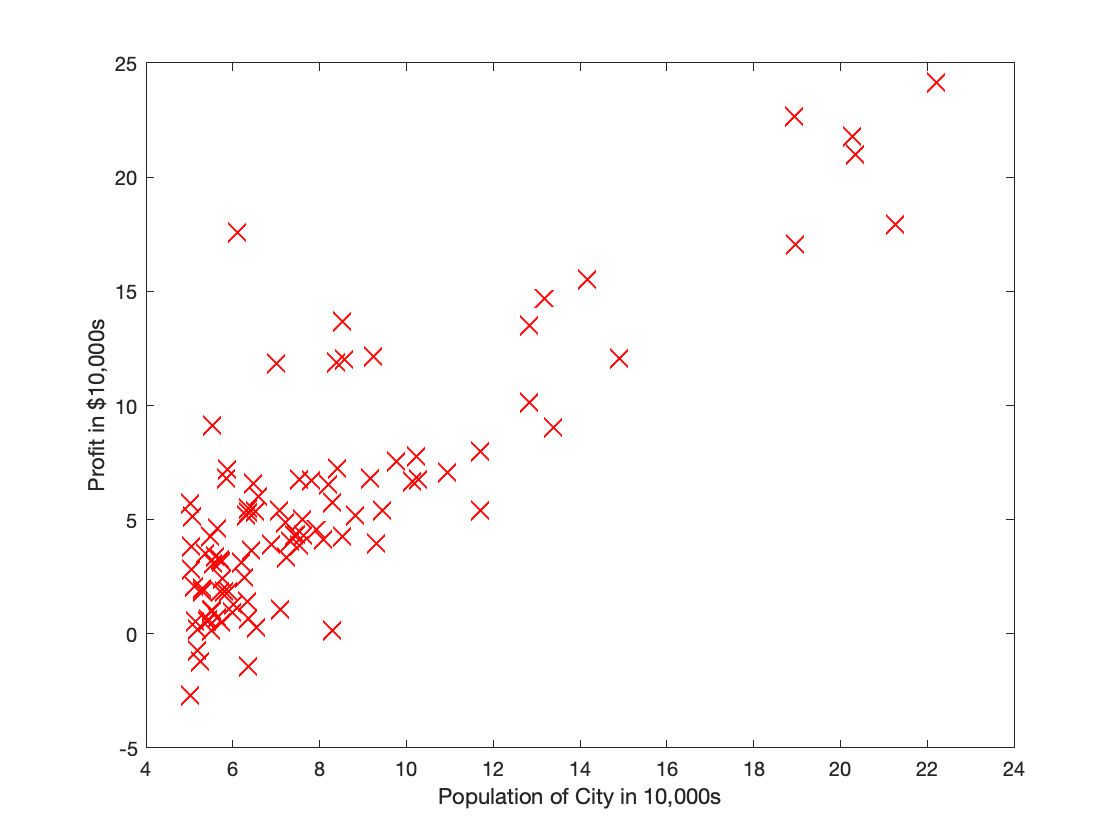

data = load('ex1data1.txt');
X = data(:, 1); y = data(:, 2);
m = length(y); % number of training examples

% Plot Data
% Note: You have to complete the code in plotData.m
plotData(X, y);


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


m

m = 97

X

X =     6.1101
    5.5277
    8.5186
    7.0032
    5.8598
    8.3829
    7.4764
    8.5781
    6.4862
    5.0546


y

y =    17.5920
    9.1302
   13.6620
   11.8540
    6.8233
   11.8860
    4.3483
   12.0000
    6.5987
    3.8166


pause;

## =================== Part 3: Gradient descent ===================

fprintf('Running Gradient Descent ...\n')

Running Gradient Descent ...



X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters

% Some gradient descent settings
iterations = 1500;
alpha = 0.01; %learning rate

X(:,2)

ans =     6.1101
    5.5277
    8.5186
    7.0032
    5.8598
    8.3829
    7.4764
    8.5781
    6.4862
    5.0546


y

y =    17.5920
    9.1302
   13.6620
   11.8540
    6.8233
   11.8860
    4.3483
   12.0000
    6.5987
    3.8166


theta

theta =      0
     0




% compute and display initial cost
computeCost(X, y, theta)

ans = 32.0727


% run gradient descent
theta = gradientDescent(X, y, theta, alpha, iterations);

theta0 = 0.0584

theta1 = 0.6533

theta0 = 0.0629

theta1 = 0.7700

theta0 = 0.0578

theta1 = 0.7913

theta0 = 0.0511

theta1 = 0.7957

theta0 = 0.0440

theta1 = 0.7971

theta0 = 0.0369

theta1 = 0.7979

theta0 = 0.0298

theta1 = 0.7987

theta0 = 0.0228

theta1 = 0.7994

theta0 = 0.0157

theta1 = 0.8001

theta0 = 0.0086

theta1 = 0.8008

theta0 = 0.0016

theta1 = 0.8015

theta0 = -0.0054

theta1 = 0.8022

theta0 = -0.0124

theta1 = 0.8029

theta0 = -0.0194

theta1 = 0.8036

theta0 = -0.0264

theta1 = 0.8043

theta0 = -0.0334

theta1 = 0.8050

theta0 = -0.0404

theta1 = 0.8057

theta0 = -0.0473

theta1 = 0.8064

theta0 = -0.0542

theta1 = 0.8071

theta0 = -0.0612

theta1 = 0.8078

theta0 = -0.0681

theta1 = 0.8085

theta0 = -0.0750

theta1 = 0.8092

theta0 = -0.0819

theta1 = 0.8099

theta0 = -0.0887

theta1 = 0.8106

theta0 = -0.0956

theta1 = 0.8113

theta0 = -0.1025

theta1 = 0.8120

theta0 = -0.1093

theta1 = 0.8126

theta0 = -0.1161

theta1 = 0.8133

theta0 = -0.1229

theta1 = 0.8140

theta0 = -0.1297

theta1 = 0.8147

theta0 = -0.1365

theta1 = 0.8154

theta0 = -0.1433

theta1 = 0.8161

theta0 = -0.1501

theta1 = 0.8167

theta0 = -0.1568

theta1 = 0.8174

theta0 = -0.1636

theta1 = 0.8181

theta0 = -0.1703

theta1 = 0.8188

theta0 = -0.1770

theta1 = 0.8194

theta0 = -0.1837

theta1 = 0.8201

theta0 = -0.1904

theta1 = 0.8208

theta0 = -0.1971

theta1 = 0.8215

theta0 = -0.2037

theta1 = 0.8221

theta0 = -0.2104

theta1 = 0.8228

theta0 = -0.2170

theta1 = 0.8235

theta0 = -0.2237

theta1 = 0.8241

theta0 = -0.2303

theta1 = 0.8248

theta0 = -0.2369

theta1 = 0.8255

theta0 = -0.2435

theta1 = 0.8261

theta0 = -0.2501

theta1 = 0.8268

theta0 = -0.2566

theta1 = 0.8274

theta0 = -0.2632

theta1 = 0.8281

theta0 = -0.2698

theta1 = 0.8288

theta0 = -0.2763

theta1 = 0.8294

theta0 = -0.2828

theta1 = 0.8301

theta0 = -0.2893

theta1 = 0.8307

theta0 = -0.2958

theta1 = 0.8314

theta0 = -0.3023

theta1 = 0.8320

theta0 = -0.3088

theta1 = 0.8327

theta0 = -0.3153

theta1 = 0.8333

theta0 = -0.3217

theta1 = 0.8340

theta0 = -0.3282

theta1 = 0.8346

theta0 = -0.3346

theta1 = 0.8353

theta0 = -0.3410

theta1 = 0.8359

theta0 = -0.3474

theta1 = 0.8366

theta0 = -0.3538

theta1 = 0.8372

theta0 = -0.3602

theta1 = 0.8378

theta0 = -0.3666

theta1 = 0.8385

theta0 = -0.3729

theta1 = 0.8391

theta0 = -0.3793

theta1 = 0.8398

theta0 = -0.3856

theta1 = 0.8404

theta0 = -0.3919

theta1 = 0.8410

theta0 = -0.3983

theta1 = 0.8417

theta0 = -0.4046

theta1 = 0.8423

theta0 = -0.4109

theta1 = 0.8429

theta0 = -0.4171

theta1 = 0.8436

theta0 = -0.4234

theta1 = 0.8442

theta0 = -0.4297

theta1 = 0.8448

theta0 = -0.4359

theta1 = 0.8455

theta0 = -0.4422

theta1 = 0.8461

theta0 = -0.4484

theta1 = 0.8467

theta0 = -0.4546

theta1 = 0.8473

theta0 = -0.4608

theta1 = 0.8480

theta0 = -0.4670

theta1 = 0.8486

theta0 = -0.4732

theta1 = 0.8492

theta0 = -0.4793

theta1 = 0.8498

theta0 = -0.4855

theta1 = 0.8504

theta0 = -0.4916

theta1 = 0.8511

theta0 = -0.4978

theta1 = 0.8517

theta0 = -0.5039

theta1 = 0.8523

theta0 = -0.5100

theta1 = 0.8529

theta0 = -0.5161

theta1 = 0.8535

theta0 = -0.5222

theta1 = 0.8541

theta0 = -0.5283

theta1 = 0.8547

theta0 = -0.5344

theta1 = 0.8553

theta0 = -0.5404

theta1 = 0.8560

theta0 = -0.5465

theta1 = 0.8566

theta0 = -0.5525

theta1 = 0.8572

theta0 = -0.5585

theta1 = 0.8578

theta0 = -0.5646

theta1 = 0.8584

theta0 = -0.5706

theta1 = 0.8590

theta0 = -0.5766

theta1 = 0.8596

theta0 = -0.5825

theta1 = 0.8602

theta0 = -0.5885

theta1 = 0.8608

theta0 = -0.5945

theta1 = 0.8614

theta0 = -0.6004

theta1 = 0.8620

theta0 = -0.6064

theta1 = 0.8626

theta0 = -0.6123

theta1 = 0.8632

theta0 = -0.6182

theta1 = 0.8638

theta0 = -0.6241

theta1 = 0.8644

theta0 = -0.6300

theta1 = 0.8650

theta0 = -0.6359

theta1 = 0.8655

theta0 = -0.6418

theta1 = 0.8661

theta0 = -0.6476

theta1 = 0.8667

theta0 = -0.6535

theta1 = 0.8673

theta0 = -0.6593

theta1 = 0.8679

theta0 = -0.6652

theta1 = 0.8685

theta0 = -0.6710

theta1 = 0.8691

theta0 = -0.6768

theta1 = 0.8697

theta0 = -0.6826

theta1 = 0.8702

theta0 = -0.6884

theta1 = 0.8708

theta0 = -0.6942

theta1 = 0.8714

theta0 = -0.7000

theta1 = 0.8720

theta0 = -0.7057

theta1 = 0.8726

theta0 = -0.7115

theta1 = 0.8731

theta0 = -0.7172

theta1 = 0.8737

theta0 = -0.7229

theta1 = 0.8743

theta0 = -0.7287

theta1 = 0.8749

theta0 = -0.7344

theta1 = 0.8754

theta0 = -0.7401

theta1 = 0.8760

theta0 = -0.7458

theta1 = 0.8766

theta0 = -0.7514

theta1 = 0.8772

theta0 = -0.7571

theta1 = 0.8777

theta0 = -0.7628

theta1 = 0.8783

theta0 = -0.7684

theta1 = 0.8789

theta0 = -0.7740

theta1 = 0.8794

theta0 = -0.7797

theta1 = 0.8800

theta0 = -0.7853

theta1 = 0.8806

theta0 = -0.7909

theta1 = 0.8811

theta0 = -0.7965

theta1 = 0.8817

theta0 = -0.8021

theta1 = 0.8822

theta0 = -0.8077

theta1 = 0.8828

theta0 = -0.8132

theta1 = 0.8834

theta0 = -0.8188

theta1 = 0.8839

theta0 = -0.8243

theta1 = 0.8845

theta0 = -0.8299

theta1 = 0.8850

theta0 = -0.8354

theta1 = 0.8856

theta0 = -0.8409

theta1 = 0.8861

theta0 = -0.8464

theta1 = 0.8867

theta0 = -0.8519

theta1 = 0.8872

theta0 = -0.8574

theta1 = 0.8878

theta0 = -0.8629

theta1 = 0.8883

theta0 = -0.8683

theta1 = 0.8889

theta0 = -0.8738

theta1 = 0.8894

theta0 = -0.8793

theta1 = 0.8900

theta0 = -0.8847

theta1 = 0.8905

theta0 = -0.8901

theta1 = 0.8911

theta0 = -0.8955

theta1 = 0.8916

theta0 = -0.9009

theta1 = 0.8922

theta0 = -0.9063

theta1 = 0.8927

theta0 = -0.9117

theta1 = 0.8933

theta0 = -0.9171

theta1 = 0.8938

theta0 = -0.9225

theta1 = 0.8943

theta0 = -0.9278

theta1 = 0.8949

theta0 = -0.9332

theta1 = 0.8954

theta0 = -0.9385

theta1 = 0.8959

theta0 = -0.9439

theta1 = 0.8965

theta0 = -0.9492

theta1 = 0.8970

theta0 = -0.9545

theta1 = 0.8975

theta0 = -0.9598

theta1 = 0.8981

theta0 = -0.9651

theta1 = 0.8986

theta0 = -0.9704

theta1 = 0.8991

theta0 = -0.9756

theta1 = 0.8997

theta0 = -0.9809

theta1 = 0.9002

theta0 = -0.9862

theta1 = 0.9007

theta0 = -0.9914

theta1 = 0.9013

theta0 = -0.9966

theta1 = 0.9018

theta0 = -1.0019

theta1 = 0.9023

theta0 = -1.0071

theta1 = 0.9028

theta0 = -1.0123

theta1 = 0.9034

theta0 = -1.0175

theta1 = 0.9039

theta0 = -1.0227

theta1 = 0.9044

theta0 = -1.0279

theta1 = 0.9049

theta0 = -1.0330

theta1 = 0.9054

theta0 = -1.0382

theta1 = 0.9060

theta0 = -1.0433

theta1 = 0.9065

theta0 = -1.0485

theta1 = 0.9070

theta0 = -1.0536

theta1 = 0.9075

theta0 = -1.0587

theta1 = 0.9080

theta0 = -1.0638

theta1 = 0.9085

theta0 = -1.0690

theta1 = 0.9090

theta0 = -1.0740

theta1 = 0.9096

theta0 = -1.0791

theta1 = 0.9101

theta0 = -1.0842

theta1 = 0.9106

theta0 = -1.0893

theta1 = 0.9111

theta0 = -1.0943

theta1 = 0.9116

theta0 = -1.0994

theta1 = 0.9121

theta0 = -1.1044

theta1 = 0.9126

theta0 = -1.1095

theta1 = 0.9131

theta0 = -1.1145

theta1 = 0.9136

theta0 = -1.1195

theta1 = 0.9141

theta0 = -1.1245

theta1 = 0.9146

theta0 = -1.1295

theta1 = 0.9151

theta0 = -1.1345

theta1 = 0.9156

theta0 = -1.1395

theta1 = 0.9161

theta0 = -1.1444

theta1 = 0.9166

theta0 = -1.1494

theta1 = 0.9171

theta0 = -1.1543

theta1 = 0.9176

theta0 = -1.1593

theta1 = 0.9181

theta0 = -1.1642

theta1 = 0.9186

theta0 = -1.1691

theta1 = 0.9191

theta0 = -1.1741

theta1 = 0.9196

theta0 = -1.1790

theta1 = 0.9201

theta0 = -1.1839

theta1 = 0.9206

theta0 = -1.1887

theta1 = 0.9211

theta0 = -1.1936

theta1 = 0.9216

theta0 = -1.1985

theta1 = 0.9221

theta0 = -1.2034

theta1 = 0.9226

theta0 = -1.2082

theta1 = 0.9230

theta0 = -1.2131

theta1 = 0.9235

theta0 = -1.2179

theta1 = 0.9240

theta0 = -1.2227

theta1 = 0.9245

theta0 = -1.2275

theta1 = 0.9250

theta0 = -1.2323

theta1 = 0.9255

theta0 = -1.2371

theta1 = 0.9259

theta0 = -1.2419

theta1 = 0.9264

theta0 = -1.2467

theta1 = 0.9269

theta0 = -1.2515

theta1 = 0.9274

theta0 = -1.2563

theta1 = 0.9279

theta0 = -1.2610

theta1 = 0.9283

theta0 = -1.2658

theta1 = 0.9288

theta0 = -1.2705

theta1 = 0.9293

theta0 = -1.2752

theta1 = 0.9298

theta0 = -1.2800

theta1 = 0.9302

theta0 = -1.2847

theta1 = 0.9307

theta0 = -1.2894

theta1 = 0.9312

theta0 = -1.2941

theta1 = 0.9317

theta0 = -1.2988

theta1 = 0.9321

theta0 = -1.3035

theta1 = 0.9326

theta0 = -1.3081

theta1 = 0.9331

theta0 = -1.3128

theta1 = 0.9335

theta0 = -1.3175

theta1 = 0.9340

theta0 = -1.3221

theta1 = 0.9345

theta0 = -1.3267

theta1 = 0.9349

theta0 = -1.3314

theta1 = 0.9354

theta0 = -1.3360

theta1 = 0.9359

theta0 = -1.3406

theta1 = 0.9363

theta0 = -1.3452

theta1 = 0.9368

theta0 = -1.3498

theta1 = 0.9373

theta0 = -1.3544

theta1 = 0.9377

theta0 = -1.3590

theta1 = 0.9382

theta0 = -1.3636

theta1 = 0.9386

theta0 = -1.3681

theta1 = 0.9391

theta0 = -1.3727

theta1 = 0.9396

theta0 = -1.3772

theta1 = 0.9400

theta0 = -1.3818

theta1 = 0.9405

theta0 = -1.3863

theta1 = 0.9409

theta0 = -1.3908

theta1 = 0.9414

theta0 = -1.3953

theta1 = 0.9418

theta0 = -1.3998

theta1 = 0.9423

theta0 = -1.4043

theta1 = 0.9427

theta0 = -1.4088

theta1 = 0.9432

theta0 = -1.4133

theta1 = 0.9436

theta0 = -1.4178

theta1 = 0.9441

theta0 = -1.4223

theta1 = 0.9445

theta0 = -1.4267

theta1 = 0.9450

theta0 = -1.4312

theta1 = 0.9454

theta0 = -1.4356

theta1 = 0.9459

theta0 = -1.4400

theta1 = 0.9463

theta0 = -1.4445

theta1 = 0.9468

theta0 = -1.4489

theta1 = 0.9472

theta0 = -1.4533

theta1 = 0.9477

theta0 = -1.4577

theta1 = 0.9481

theta0 = -1.4621

theta1 = 0.9485

theta0 = -1.4665

theta1 = 0.9490

theta0 = -1.4709

theta1 = 0.9494

theta0 = -1.4752

theta1 = 0.9499

theta0 = -1.4796

theta1 = 0.9503

theta0 = -1.4840

theta1 = 0.9507

theta0 = -1.4883

theta1 = 0.9512

theta0 = -1.4926

theta1 = 0.9516

theta0 = -1.4970

theta1 = 0.9520

theta0 = -1.5013

theta1 = 0.9525

theta0 = -1.5056

theta1 = 0.9529

theta0 = -1.5099

theta1 = 0.9533

theta0 = -1.5142

theta1 = 0.9538

theta0 = -1.5185

theta1 = 0.9542

theta0 = -1.5228

theta1 = 0.9546

theta0 = -1.5271

theta1 = 0.9551

theta0 = -1.5313

theta1 = 0.9555

theta0 = -1.5356

theta1 = 0.9559

theta0 = -1.5399

theta1 = 0.9564

theta0 = -1.5441

theta1 = 0.9568

theta0 = -1.5484

theta1 = 0.9572

theta0 = -1.5526

theta1 = 0.9576

theta0 = -1.5568

theta1 = 0.9581

theta0 = -1.5610

theta1 = 0.9585

theta0 = -1.5652

theta1 = 0.9589

theta0 = -1.5694

theta1 = 0.9593

theta0 = -1.5736

theta1 = 0.9597

theta0 = -1.5778

theta1 = 0.9602

theta0 = -1.5820

theta1 = 0.9606

theta0 = -1.5862

theta1 = 0.9610

theta0 = -1.5903

theta1 = 0.9614

theta0 = -1.5945

theta1 = 0.9618

theta0 = -1.5986

theta1 = 0.9623

theta0 = -1.6028

theta1 = 0.9627

theta0 = -1.6069

theta1 = 0.9631

theta0 = -1.6110

theta1 = 0.9635

theta0 = -1.6151

theta1 = 0.9639

theta0 = -1.6193

theta1 = 0.9643

theta0 = -1.6234

theta1 = 0.9647

theta0 = -1.6275

theta1 = 0.9652

theta0 = -1.6315

theta1 = 0.9656

theta0 = -1.6356

theta1 = 0.9660

theta0 = -1.6397

theta1 = 0.9664

theta0 = -1.6438

theta1 = 0.9668

theta0 = -1.6478

theta1 = 0.9672

theta0 = -1.6519

theta1 = 0.9676

theta0 = -1.6559

theta1 = 0.9680

theta0 = -1.6600

theta1 = 0.9684

theta0 = -1.6640

theta1 = 0.9688

theta0 = -1.6680

theta1 = 0.9692

theta0 = -1.6720

theta1 = 0.9696

theta0 = -1.6760

theta1 = 0.9700

theta0 = -1.6800

theta1 = 0.9704

theta0 = -1.6840

theta1 = 0.9708

theta0 = -1.6880

theta1 = 0.9712

theta0 = -1.6920

theta1 = 0.9716

theta0 = -1.6960

theta1 = 0.9720

theta0 = -1.6999

theta1 = 0.9724

theta0 = -1.7039

theta1 = 0.9728

theta0 = -1.7079

theta1 = 0.9732

theta0 = -1.7118

theta1 = 0.9736

theta0 = -1.7157

theta1 = 0.9740

theta0 = -1.7197

theta1 = 0.9744

theta0 = -1.7236

theta1 = 0.9748

theta0 = -1.7275

theta1 = 0.9752

theta0 = -1.7314

theta1 = 0.9756

theta0 = -1.7353

theta1 = 0.9760

theta0 = -1.7392

theta1 = 0.9764

theta0 = -1.7431

theta1 = 0.9768

theta0 = -1.7470

theta1 = 0.9772

theta0 = -1.7508

theta1 = 0.9776

theta0 = -1.7547

theta1 = 0.9779

theta0 = -1.7586

theta1 = 0.9783

theta0 = -1.7624

theta1 = 0.9787

theta0 = -1.7663

theta1 = 0.9791

theta0 = -1.7701

theta1 = 0.9795

theta0 = -1.7739

theta1 = 0.9799

theta0 = -1.7778

theta1 = 0.9803

theta0 = -1.7816

theta1 = 0.9806

theta0 = -1.7854

theta1 = 0.9810

theta0 = -1.7892

theta1 = 0.9814

theta0 = -1.7930

theta1 = 0.9818

theta0 = -1.7968

theta1 = 0.9822

theta0 = -1.8006

theta1 = 0.9825

theta0 = -1.8043

theta1 = 0.9829

theta0 = -1.8081

theta1 = 0.9833

theta0 = -1.8119

theta1 = 0.9837

theta0 = -1.8156

theta1 = 0.9841

theta0 = -1.8194

theta1 = 0.9844

theta0 = -1.8231

theta1 = 0.9848

theta0 = -1.8269

theta1 = 0.9852

theta0 = -1.8306

theta1 = 0.9856

theta0 = -1.8343

theta1 = 0.9859

theta0 = -1.8380

theta1 = 0.9863

theta0 = -1.8417

theta1 = 0.9867

theta0 = -1.8454

theta1 = 0.9871

theta0 = -1.8491

theta1 = 0.9874

theta0 = -1.8528

theta1 = 0.9878

theta0 = -1.8565

theta1 = 0.9882

theta0 = -1.8602

theta1 = 0.9885

theta0 = -1.8639

theta1 = 0.9889

theta0 = -1.8675

theta1 = 0.9893

theta0 = -1.8712

theta1 = 0.9896

theta0 = -1.8748

theta1 = 0.9900

theta0 = -1.8785

theta1 = 0.9904

theta0 = -1.8821

theta1 = 0.9907

theta0 = -1.8857

theta1 = 0.9911

theta0 = -1.8894

theta1 = 0.9915

theta0 = -1.8930

theta1 = 0.9918

theta0 = -1.8966

theta1 = 0.9922

theta0 = -1.9002

theta1 = 0.9926

theta0 = -1.9038

theta1 = 0.9929

theta0 = -1.9074

theta1 = 0.9933

theta0 = -1.9110

theta1 = 0.9936

theta0 = -1.9145

theta1 = 0.9940

theta0 = -1.9181

theta1 = 0.9944

theta0 = -1.9217

theta1 = 0.9947

theta0 = -1.9252

theta1 = 0.9951

theta0 = -1.9288

theta1 = 0.9954

theta0 = -1.9323

theta1 = 0.9958

theta0 = -1.9359

theta1 = 0.9961

theta0 = -1.9394

theta1 = 0.9965

theta0 = -1.9429

theta1 = 0.9968

theta0 = -1.9465

theta1 = 0.9972

theta0 = -1.9500

theta1 = 0.9976

theta0 = -1.9535

theta1 = 0.9979

theta0 = -1.9570

theta1 = 0.9983

theta0 = -1.9605

theta1 = 0.9986

theta0 = -1.9640

theta1 = 0.9990

theta0 = -1.9674

theta1 = 0.9993

theta0 = -1.9709

theta1 = 0.9997

theta0 = -1.9744

theta1 = 1.0000

theta0 = -1.9778

theta1 = 1.0004

theta0 = -1.9813

theta1 = 1.0007

theta0 = -1.9848

theta1 = 1.0011

theta0 = -1.9882

theta1 = 1.0014

theta0 = -1.9916

theta1 = 1.0017

theta0 = -1.9951

theta1 = 1.0021

theta0 = -1.9985

theta1 = 1.0024

theta0 = -2.0019

theta1 = 1.0028

theta0 = -2.0053

theta1 = 1.0031

theta0 = -2.0087

theta1 = 1.0035

theta0 = -2.0121

theta1 = 1.0038

theta0 = -2.0155

theta1 = 1.0041

theta0 = -2.0189

theta1 = 1.0045

theta0 = -2.0223

theta1 = 1.0048

theta0 = -2.0257

theta1 = 1.0052

theta0 = -2.0291

theta1 = 1.0055

theta0 = -2.0324

theta1 = 1.0058

theta0 = -2.0358

theta1 = 1.0062

theta0 = -2.0391

theta1 = 1.0065

theta0 = -2.0425

theta1 = 1.0068

theta0 = -2.0458

theta1 = 1.0072

theta0 = -2.0492

theta1 = 1.0075

theta0 = -2.0525

theta1 = 1.0079

theta0 = -2.0558

theta1 = 1.0082

theta0 = -2.0591

theta1 = 1.0085

theta0 = -2.0624

theta1 = 1.0089

theta0 = -2.0657

theta1 = 1.0092

theta0 = -2.0690

theta1 = 1.0095

theta0 = -2.0723

theta1 = 1.0098

theta0 = -2.0756

theta1 = 1.0102

theta0 = -2.0789

theta1 = 1.0105

theta0 = -2.0822

theta1 = 1.0108

theta0 = -2.0854

theta1 = 1.0112

theta0 = -2.0887

theta1 = 1.0115

theta0 = -2.0920

theta1 = 1.0118

theta0 = -2.0952

theta1 = 1.0121

theta0 = -2.0985

theta1 = 1.0125

theta0 = -2.1017

theta1 = 1.0128

theta0 = -2.1049

theta1 = 1.0131

theta0 = -2.1082

theta1 = 1.0134

theta0 = -2.1114

theta1 = 1.0138

theta0 = -2.1146

theta1 = 1.0141

theta0 = -2.1178

theta1 = 1.0144

theta0 = -2.1210

theta1 = 1.0147

theta0 = -2.1242

theta1 = 1.0151

theta0 = -2.1274

theta1 = 1.0154

theta0 = -2.1306

theta1 = 1.0157

theta0 = -2.1338

theta1 = 1.0160

theta0 = -2.1370

theta1 = 1.0163

theta0 = -2.1401

theta1 = 1.0167

theta0 = -2.1433

theta1 = 1.0170

theta0 = -2.1465

theta1 = 1.0173

theta0 = -2.1496

theta1 = 1.0176

theta0 = -2.1528

theta1 = 1.0179

theta0 = -2.1559

theta1 = 1.0182

theta0 = -2.1590

theta1 = 1.0186

theta0 = -2.1622

theta1 = 1.0189

theta0 = -2.1653

theta1 = 1.0192

theta0 = -2.1684

theta1 = 1.0195

theta0 = -2.1715

theta1 = 1.0198

theta0 = -2.1746

theta1 = 1.0201

theta0 = -2.1777

theta1 = 1.0204

theta0 = -2.1808

theta1 = 1.0207

theta0 = -2.1839

theta1 = 1.0211

theta0 = -2.1870

theta1 = 1.0214

theta0 = -2.1901

theta1 = 1.0217

theta0 = -2.1932

theta1 = 1.0220

theta0 = -2.1962

theta1 = 1.0223

theta0 = -2.1993

theta1 = 1.0226

theta0 = -2.2024

theta1 = 1.0229

theta0 = -2.2054

theta1 = 1.0232

theta0 = -2.2085

theta1 = 1.0235

theta0 = -2.2115

theta1 = 1.0238

theta0 = -2.2145

theta1 = 1.0241

theta0 = -2.2176

theta1 = 1.0244

theta0 = -2.2206

theta1 = 1.0247

theta0 = -2.2236

theta1 = 1.0250

theta0 = -2.2266

theta1 = 1.0253

theta0 = -2.2296

theta1 = 1.0257

theta0 = -2.2326

theta1 = 1.0260

theta0 = -2.2356

theta1 = 1.0263

theta0 = -2.2386

theta1 = 1.0266

theta0 = -2.2416

theta1 = 1.0269

theta0 = -2.2446

theta1 = 1.0272

theta0 = -2.2476

theta1 = 1.0275

theta0 = -2.2505

theta1 = 1.0278

theta0 = -2.2535

theta1 = 1.0280

theta0 = -2.2565

theta1 = 1.0283

theta0 = -2.2594

theta1 = 1.0286

theta0 = -2.2624

theta1 = 1.0289

theta0 = -2.2653

theta1 = 1.0292

theta0 = -2.2683

theta1 = 1.0295

theta0 = -2.2712

theta1 = 1.0298

theta0 = -2.2741

theta1 = 1.0301

theta0 = -2.2770

theta1 = 1.0304

theta0 = -2.2800

theta1 = 1.0307

theta0 = -2.2829

theta1 = 1.0310

theta0 = -2.2858

theta1 = 1.0313

theta0 = -2.2887

theta1 = 1.0316

theta0 = -2.2916

theta1 = 1.0319

theta0 = -2.2945

theta1 = 1.0322

theta0 = -2.2974

theta1 = 1.0325

theta0 = -2.3002

theta1 = 1.0327

theta0 = -2.3031

theta1 = 1.0330

theta0 = -2.3060

theta1 = 1.0333

theta0 = -2.3088

theta1 = 1.0336

theta0 = -2.3117

theta1 = 1.0339

theta0 = -2.3146

theta1 = 1.0342

theta0 = -2.3174

theta1 = 1.0345

theta0 = -2.3203

theta1 = 1.0348

theta0 = -2.3231

theta1 = 1.0350

theta0 = -2.3259

theta1 = 1.0353

theta0 = -2.3288

theta1 = 1.0356

theta0 = -2.3316

theta1 = 1.0359

theta0 = -2.3344

theta1 = 1.0362

theta0 = -2.3372

theta1 = 1.0365

theta0 = -2.3400

theta1 = 1.0367

theta0 = -2.3428

theta1 = 1.0370

theta0 = -2.3456

theta1 = 1.0373

theta0 = -2.3484

theta1 = 1.0376

theta0 = -2.3512

theta1 = 1.0379

theta0 = -2.3540

theta1 = 1.0381

theta0 = -2.3568

theta1 = 1.0384

theta0 = -2.3596

theta1 = 1.0387

theta0 = -2.3623

theta1 = 1.0390

theta0 = -2.3651

theta1 = 1.0393

theta0 = -2.3678

theta1 = 1.0395

theta0 = -2.3706

theta1 = 1.0398

theta0 = -2.3734

theta1 = 1.0401

theta0 = -2.3761

theta1 = 1.0404

theta0 = -2.3788

theta1 = 1.0406

theta0 = -2.3816

theta1 = 1.0409

theta0 = -2.3843

theta1 = 1.0412

theta0 = -2.3870

theta1 = 1.0415

theta0 = -2.3897

theta1 = 1.0417

theta0 = -2.3925

theta1 = 1.0420

theta0 = -2.3952

theta1 = 1.0423

theta0 = -2.3979

theta1 = 1.0426

theta0 = -2.4006

theta1 = 1.0428

theta0 = -2.4033

theta1 = 1.0431

theta0 = -2.4060

theta1 = 1.0434

theta0 = -2.4086

theta1 = 1.0436

theta0 = -2.4113

theta1 = 1.0439

theta0 = -2.4140

theta1 = 1.0442

theta0 = -2.4167

theta1 = 1.0444

theta0 = -2.4193

theta1 = 1.0447

theta0 = -2.4220

theta1 = 1.0450

theta0 = -2.4247

theta1 = 1.0452

theta0 = -2.4273

theta1 = 1.0455

theta0 = -2.4300

theta1 = 1.0458

theta0 = -2.4326

theta1 = 1.0460

theta0 = -2.4352

theta1 = 1.0463

theta0 = -2.4379

theta1 = 1.0466

theta0 = -2.4405

theta1 = 1.0468

theta0 = -2.4431

theta1 = 1.0471

theta0 = -2.4457

theta1 = 1.0474

theta0 = -2.4484

theta1 = 1.0476

theta0 = -2.4510

theta1 = 1.0479

theta0 = -2.4536

theta1 = 1.0481

theta0 = -2.4562

theta1 = 1.0484

theta0 = -2.4588

theta1 = 1.0487

theta0 = -2.4614

theta1 = 1.0489

theta0 = -2.4639

theta1 = 1.0492

theta0 = -2.4665

theta1 = 1.0494

theta0 = -2.4691

theta1 = 1.0497

theta0 = -2.4717

theta1 = 1.0500

theta0 = -2.4742

theta1 = 1.0502

theta0 = -2.4768

theta1 = 1.0505

theta0 = -2.4794

theta1 = 1.0507

theta0 = -2.4819

theta1 = 1.0510

theta0 = -2.4845

theta1 = 1.0513

theta0 = -2.4870

theta1 = 1.0515

theta0 = -2.4895

theta1 = 1.0518

theta0 = -2.4921

theta1 = 1.0520

theta0 = -2.4946

theta1 = 1.0523

theta0 = -2.4971

theta1 = 1.0525

theta0 = -2.4997

theta1 = 1.0528

theta0 = -2.5022

theta1 = 1.0530

theta0 = -2.5047

theta1 = 1.0533

theta0 = -2.5072

theta1 = 1.0535

theta0 = -2.5097

theta1 = 1.0538

theta0 = -2.5122

theta1 = 1.0540

theta0 = -2.5147

theta1 = 1.0543

theta0 = -2.5172

theta1 = 1.0545

theta0 = -2.5197

theta1 = 1.0548

theta0 = -2.5221

theta1 = 1.0550

theta0 = -2.5246

theta1 = 1.0553

theta0 = -2.5271

theta1 = 1.0555

theta0 = -2.5296

theta1 = 1.0558

theta0 = -2.5320

theta1 = 1.0560

theta0 = -2.5345

theta1 = 1.0563

theta0 = -2.5369

theta1 = 1.0565

theta0 = -2.5394

theta1 = 1.0568

theta0 = -2.5418

theta1 = 1.0570

theta0 = -2.5443

theta1 = 1.0573

theta0 = -2.5467

theta1 = 1.0575

theta0 = -2.5491

theta1 = 1.0577

theta0 = -2.5516

theta1 = 1.0580

theta0 = -2.5540

theta1 = 1.0582

theta0 = -2.5564

theta1 = 1.0585

theta0 = -2.5588

theta1 = 1.0587

theta0 = -2.5612

theta1 = 1.0590

theta0 = -2.5636

theta1 = 1.0592

theta0 = -2.5660

theta1 = 1.0594

theta0 = -2.5684

theta1 = 1.0597

theta0 = -2.5708

theta1 = 1.0599

theta0 = -2.5732

theta1 = 1.0602

theta0 = -2.5756

theta1 = 1.0604

theta0 = -2.5780

theta1 = 1.0606

theta0 = -2.5803

theta1 = 1.0609

theta0 = -2.5827

theta1 = 1.0611

theta0 = -2.5851

theta1 = 1.0614

theta0 = -2.5874

theta1 = 1.0616

theta0 = -2.5898

theta1 = 1.0618

theta0 = -2.5922

theta1 = 1.0621

theta0 = -2.5945

theta1 = 1.0623

theta0 = -2.5969

theta1 = 1.0625

theta0 = -2.5992

theta1 = 1.0628

theta0 = -2.6015

theta1 = 1.0630

theta0 = -2.6039

theta1 = 1.0632

theta0 = -2.6062

theta1 = 1.0635

theta0 = -2.6085

theta1 = 1.0637

theta0 = -2.6108

theta1 = 1.0639

theta0 = -2.6132

theta1 = 1.0642

theta0 = -2.6155

theta1 = 1.0644

theta0 = -2.6178

theta1 = 1.0646

theta0 = -2.6201

theta1 = 1.0649

theta0 = -2.6224

theta1 = 1.0651

theta0 = -2.6247

theta1 = 1.0653

theta0 = -2.6270

theta1 = 1.0656

theta0 = -2.6293

theta1 = 1.0658

theta0 = -2.6315

theta1 = 1.0660

theta0 = -2.6338

theta1 = 1.0663

theta0 = -2.6361

theta1 = 1.0665

theta0 = -2.6384

theta1 = 1.0667

theta0 = -2.6406

theta1 = 1.0669

theta0 = -2.6429

theta1 = 1.0672

theta0 = -2.6452

theta1 = 1.0674

theta0 = -2.6474

theta1 = 1.0676

theta0 = -2.6497

theta1 = 1.0678

theta0 = -2.6519

theta1 = 1.0681

theta0 = -2.6541

theta1 = 1.0683

theta0 = -2.6564

theta1 = 1.0685

theta0 = -2.6586

theta1 = 1.0687

theta0 = -2.6608

theta1 = 1.0690

theta0 = -2.6631

theta1 = 1.0692

theta0 = -2.6653

theta1 = 1.0694

theta0 = -2.6675

theta1 = 1.0696

theta0 = -2.6697

theta1 = 1.0699

theta0 = -2.6719

theta1 = 1.0701

theta0 = -2.6741

theta1 = 1.0703

theta0 = -2.6763

theta1 = 1.0705

theta0 = -2.6785

theta1 = 1.0707

theta0 = -2.6807

theta1 = 1.0710

theta0 = -2.6829

theta1 = 1.0712

theta0 = -2.6851

theta1 = 1.0714

theta0 = -2.6873

theta1 = 1.0716

theta0 = -2.6895

theta1 = 1.0718

theta0 = -2.6916

theta1 = 1.0721

theta0 = -2.6938

theta1 = 1.0723

theta0 = -2.6960

theta1 = 1.0725

theta0 = -2.6981

theta1 = 1.0727

theta0 = -2.7003

theta1 = 1.0729

theta0 = -2.7025

theta1 = 1.0732

theta0 = -2.7046

theta1 = 1.0734

theta0 = -2.7068

theta1 = 1.0736

theta0 = -2.7089

theta1 = 1.0738

theta0 = -2.7110

theta1 = 1.0740

theta0 = -2.7132

theta1 = 1.0742

theta0 = -2.7153

theta1 = 1.0744

theta0 = -2.7174

theta1 = 1.0747

theta0 = -2.7196

theta1 = 1.0749

theta0 = -2.7217

theta1 = 1.0751

theta0 = -2.7238

theta1 = 1.0753

theta0 = -2.7259

theta1 = 1.0755

theta0 = -2.7280

theta1 = 1.0757

theta0 = -2.7301

theta1 = 1.0759

theta0 = -2.7322

theta1 = 1.0761

theta0 = -2.7343

theta1 = 1.0764

theta0 = -2.7364

theta1 = 1.0766

theta0 = -2.7385

theta1 = 1.0768

theta0 = -2.7406

theta1 = 1.0770

theta0 = -2.7427

theta1 = 1.0772

theta0 = -2.7448

theta1 = 1.0774

theta0 = -2.7468

theta1 = 1.0776

theta0 = -2.7489

theta1 = 1.0778

theta0 = -2.7510

theta1 = 1.0780

theta0 = -2.7530

theta1 = 1.0782

theta0 = -2.7551

theta1 = 1.0784

theta0 = -2.7571

theta1 = 1.0786

theta0 = -2.7592

theta1 = 1.0789

theta0 = -2.7613

theta1 = 1.0791

theta0 = -2.7633

theta1 = 1.0793

theta0 = -2.7653

theta1 = 1.0795

theta0 = -2.7674

theta1 = 1.0797

theta0 = -2.7694

theta1 = 1.0799

theta0 = -2.7714

theta1 = 1.0801

theta0 = -2.7735

theta1 = 1.0803

theta0 = -2.7755

theta1 = 1.0805

theta0 = -2.7775

theta1 = 1.0807

theta0 = -2.7795

theta1 = 1.0809

theta0 = -2.7815

theta1 = 1.0811

theta0 = -2.7835

theta1 = 1.0813

theta0 = -2.7855

theta1 = 1.0815

theta0 = -2.7876

theta1 = 1.0817

theta0 = -2.7895

theta1 = 1.0819

theta0 = -2.7915

theta1 = 1.0821

theta0 = -2.7935

theta1 = 1.0823

theta0 = -2.7955

theta1 = 1.0825

theta0 = -2.7975

theta1 = 1.0827

theta0 = -2.7995

theta1 = 1.0829

theta0 = -2.8015

theta1 = 1.0831

theta0 = -2.8034

theta1 = 1.0833

theta0 = -2.8054

theta1 = 1.0835

theta0 = -2.8074

theta1 = 1.0837

theta0 = -2.8093

theta1 = 1.0839

theta0 = -2.8113

theta1 = 1.0841

theta0 = -2.8132

theta1 = 1.0843

theta0 = -2.8152

theta1 = 1.0845

theta0 = -2.8171

theta1 = 1.0847

theta0 = -2.8191

theta1 = 1.0849

theta0 = -2.8210

theta1 = 1.0851

theta0 = -2.8230

theta1 = 1.0853

theta0 = -2.8249

theta1 = 1.0855

theta0 = -2.8268

theta1 = 1.0856

theta0 = -2.8288

theta1 = 1.0858

theta0 = -2.8307

theta1 = 1.0860

theta0 = -2.8326

theta1 = 1.0862

theta0 = -2.8345

theta1 = 1.0864

theta0 = -2.8364

theta1 = 1.0866

theta0 = -2.8383

theta1 = 1.0868

theta0 = -2.8402

theta1 = 1.0870

theta0 = -2.8421

theta1 = 1.0872

theta0 = -2.8440

theta1 = 1.0874

theta0 = -2.8459

theta1 = 1.0876

theta0 = -2.8478

theta1 = 1.0878

theta0 = -2.8497

theta1 = 1.0879

theta0 = -2.8516

theta1 = 1.0881

theta0 = -2.8535

theta1 = 1.0883

theta0 = -2.8554

theta1 = 1.0885

theta0 = -2.8572

theta1 = 1.0887

theta0 = -2.8591

theta1 = 1.0889

theta0 = -2.8610

theta1 = 1.0891

theta0 = -2.8629

theta1 = 1.0893

theta0 = -2.8647

theta1 = 1.0895

theta0 = -2.8666

theta1 = 1.0896

theta0 = -2.8684

theta1 = 1.0898

theta0 = -2.8703

theta1 = 1.0900

theta0 = -2.8721

theta1 = 1.0902

theta0 = -2.8740

theta1 = 1.0904

theta0 = -2.8758

theta1 = 1.0906

theta0 = -2.8777

theta1 = 1.0908

theta0 = -2.8795

theta1 = 1.0909

theta0 = -2.8813

theta1 = 1.0911

theta0 = -2.8831

theta1 = 1.0913

theta0 = -2.8850

theta1 = 1.0915

theta0 = -2.8868

theta1 = 1.0917

theta0 = -2.8886

theta1 = 1.0919

theta0 = -2.8904

theta1 = 1.0920

theta0 = -2.8922

theta1 = 1.0922

theta0 = -2.8941

theta1 = 1.0924

theta0 = -2.8959

theta1 = 1.0926

theta0 = -2.8977

theta1 = 1.0928

theta0 = -2.8995

theta1 = 1.0929

theta0 = -2.9013

theta1 = 1.0931

theta0 = -2.9030

theta1 = 1.0933

theta0 = -2.9048

theta1 = 1.0935

theta0 = -2.9066

theta1 = 1.0937

theta0 = -2.9084

theta1 = 1.0938

theta0 = -2.9102

theta1 = 1.0940

theta0 = -2.9120

theta1 = 1.0942

theta0 = -2.9137

theta1 = 1.0944

theta0 = -2.9155

theta1 = 1.0946

theta0 = -2.9173

theta1 = 1.0947

theta0 = -2.9190

theta1 = 1.0949

theta0 = -2.9208

theta1 = 1.0951

theta0 = -2.9226

theta1 = 1.0953

theta0 = -2.9243

theta1 = 1.0954

theta0 = -2.9261

theta1 = 1.0956

theta0 = -2.9278

theta1 = 1.0958

theta0 = -2.9296

theta1 = 1.0960

theta0 = -2.9313

theta1 = 1.0961

theta0 = -2.9330

theta1 = 1.0963

theta0 = -2.9348

theta1 = 1.0965

theta0 = -2.9365

theta1 = 1.0967

theta0 = -2.9382

theta1 = 1.0968

theta0 = -2.9400

theta1 = 1.0970

theta0 = -2.9417

theta1 = 1.0972

theta0 = -2.9434

theta1 = 1.0974

theta0 = -2.9451

theta1 = 1.0975

theta0 = -2.9468

theta1 = 1.0977

theta0 = -2.9485

theta1 = 1.0979

theta0 = -2.9502

theta1 = 1.0980

theta0 = -2.9520

theta1 = 1.0982

theta0 = -2.9537

theta1 = 1.0984

theta0 = -2.9554

theta1 = 1.0986

theta0 = -2.9570

theta1 = 1.0987

theta0 = -2.9587

theta1 = 1.0989

theta0 = -2.9604

theta1 = 1.0991

theta0 = -2.9621

theta1 = 1.0992

theta0 = -2.9638

theta1 = 1.0994

theta0 = -2.9655

theta1 = 1.0996

theta0 = -2.9672

theta1 = 1.0997

theta0 = -2.9688

theta1 = 1.0999

theta0 = -2.9705

theta1 = 1.1001

theta0 = -2.9722

theta1 = 1.1002

theta0 = -2.9738

theta1 = 1.1004

theta0 = -2.9755

theta1 = 1.1006

theta0 = -2.9772

theta1 = 1.1007

theta0 = -2.9788

theta1 = 1.1009

theta0 = -2.9805

theta1 = 1.1011

theta0 = -2.9821

theta1 = 1.1012

theta0 = -2.9838

theta1 = 1.1014

theta0 = -2.9854

theta1 = 1.1016

theta0 = -2.9870

theta1 = 1.1017

theta0 = -2.9887

theta1 = 1.1019

theta0 = -2.9903

theta1 = 1.1021

theta0 = -2.9920

theta1 = 1.1022

theta0 = -2.9936

theta1 = 1.1024

theta0 = -2.9952

theta1 = 1.1026

theta0 = -2.9968

theta1 = 1.1027

theta0 = -2.9984

theta1 = 1.1029

theta0 = -3.0001

theta1 = 1.1030

theta0 = -3.0017

theta1 = 1.1032

theta0 = -3.0033

theta1 = 1.1034

theta0 = -3.0049

theta1 = 1.1035

theta0 = -3.0065

theta1 = 1.1037

theta0 = -3.0081

theta1 = 1.1039

theta0 = -3.0097

theta1 = 1.1040

theta0 = -3.0113

theta1 = 1.1042

theta0 = -3.0129

theta1 = 1.1043

theta0 = -3.0145

theta1 = 1.1045

theta0 = -3.0161

theta1 = 1.1047

theta0 = -3.0177

theta1 = 1.1048

theta0 = -3.0193

theta1 = 1.1050

theta0 = -3.0208

theta1 = 1.1051

theta0 = -3.0224

theta1 = 1.1053

theta0 = -3.0240

theta1 = 1.1055

theta0 = -3.0256

theta1 = 1.1056

theta0 = -3.0271

theta1 = 1.1058

theta0 = -3.0287

theta1 = 1.1059

theta0 = -3.0303

theta1 = 1.1061

theta0 = -3.0318

theta1 = 1.1062

theta0 = -3.0334

theta1 = 1.1064

theta0 = -3.0349

theta1 = 1.1066

theta0 = -3.0365

theta1 = 1.1067

theta0 = -3.0380

theta1 = 1.1069

theta0 = -3.0396

theta1 = 1.1070

theta0 = -3.0411

theta1 = 1.1072

theta0 = -3.0427

theta1 = 1.1073

theta0 = -3.0442

theta1 = 1.1075

theta0 = -3.0457

theta1 = 1.1076

theta0 = -3.0473

theta1 = 1.1078

theta0 = -3.0488

theta1 = 1.1079

theta0 = -3.0503

theta1 = 1.1081

theta0 = -3.0518

theta1 = 1.1083

theta0 = -3.0534

theta1 = 1.1084

theta0 = -3.0549

theta1 = 1.1086

theta0 = -3.0564

theta1 = 1.1087

theta0 = -3.0579

theta1 = 1.1089

theta0 = -3.0594

theta1 = 1.1090

theta0 = -3.0609

theta1 = 1.1092

theta0 = -3.0624

theta1 = 1.1093

theta0 = -3.0639

theta1 = 1.1095

theta0 = -3.0654

theta1 = 1.1096

theta0 = -3.0669

theta1 = 1.1098

theta0 = -3.0684

theta1 = 1.1099

theta0 = -3.0699

theta1 = 1.1101

theta0 = -3.0714

theta1 = 1.1102

theta0 = -3.0729

theta1 = 1.1104

theta0 = -3.0744

theta1 = 1.1105

theta0 = -3.0759

theta1 = 1.1107

theta0 = -3.0773

theta1 = 1.1108

theta0 = -3.0788

theta1 = 1.1110

theta0 = -3.0803

theta1 = 1.1111

theta0 = -3.0818

theta1 = 1.1113

theta0 = -3.0832

theta1 = 1.1114

theta0 = -3.0847

theta1 = 1.1116

theta0 = -3.0861

theta1 = 1.1117

theta0 = -3.0876

theta1 = 1.1118

theta0 = -3.0891

theta1 = 1.1120

theta0 = -3.0905

theta1 = 1.1121

theta0 = -3.0920

theta1 = 1.1123

theta0 = -3.0934

theta1 = 1.1124

theta0 = -3.0949

theta1 = 1.1126

theta0 = -3.0963

theta1 = 1.1127

theta0 = -3.0977

theta1 = 1.1129

theta0 = -3.0992

theta1 = 1.1130

theta0 = -3.1006

theta1 = 1.1132

theta0 = -3.1021

theta1 = 1.1133

theta0 = -3.1035

theta1 = 1.1134

theta0 = -3.1049

theta1 = 1.1136

theta0 = -3.1063

theta1 = 1.1137

theta0 = -3.1078

theta1 = 1.1139

theta0 = -3.1092

theta1 = 1.1140

theta0 = -3.1106

theta1 = 1.1142

theta0 = -3.1120

theta1 = 1.1143

theta0 = -3.1134

theta1 = 1.1144

theta0 = -3.1148

theta1 = 1.1146

theta0 = -3.1162

theta1 = 1.1147

theta0 = -3.1177

theta1 = 1.1149

theta0 = -3.1191

theta1 = 1.1150

theta0 = -3.1205

theta1 = 1.1151

theta0 = -3.1219

theta1 = 1.1153

theta0 = -3.1232

theta1 = 1.1154

theta0 = -3.1246

theta1 = 1.1156

theta0 = -3.1260

theta1 = 1.1157

theta0 = -3.1274

theta1 = 1.1158

theta0 = -3.1288

theta1 = 1.1160

theta0 = -3.1302

theta1 = 1.1161

theta0 = -3.1316

theta1 = 1.1163

theta0 = -3.1329

theta1 = 1.1164

theta0 = -3.1343

theta1 = 1.1165

theta0 = -3.1357

theta1 = 1.1167

theta0 = -3.1371

theta1 = 1.1168

theta0 = -3.1384

theta1 = 1.1169

theta0 = -3.1398

theta1 = 1.1171

theta0 = -3.1412

theta1 = 1.1172

theta0 = -3.1425

theta1 = 1.1174

theta0 = -3.1439

theta1 = 1.1175

theta0 = -3.1452

theta1 = 1.1176

theta0 = -3.1466

theta1 = 1.1178

theta0 = -3.1479

theta1 = 1.1179

theta0 = -3.1493

theta1 = 1.1180

theta0 = -3.1506

theta1 = 1.1182

theta0 = -3.1520

theta1 = 1.1183

theta0 = -3.1533

theta1 = 1.1184

theta0 = -3.1546

theta1 = 1.1186

theta0 = -3.1560

theta1 = 1.1187

theta0 = -3.1573

theta1 = 1.1188

theta0 = -3.1587

theta1 = 1.1190

theta0 = -3.1600

theta1 = 1.1191

theta0 = -3.1613

theta1 = 1.1192

theta0 = -3.1626

theta1 = 1.1194

theta0 = -3.1640

theta1 = 1.1195

theta0 = -3.1653

theta1 = 1.1196

theta0 = -3.1666

theta1 = 1.1198

theta0 = -3.1679

theta1 = 1.1199

theta0 = -3.1692

theta1 = 1.1200

theta0 = -3.1705

theta1 = 1.1202

theta0 = -3.1718

theta1 = 1.1203

theta0 = -3.1731

theta1 = 1.1204

theta0 = -3.1744

theta1 = 1.1206

theta0 = -3.1757

theta1 = 1.1207

theta0 = -3.1770

theta1 = 1.1208

theta0 = -3.1783

theta1 = 1.1210

theta0 = -3.1796

theta1 = 1.1211

theta0 = -3.1809

theta1 = 1.1212

theta0 = -3.1822

theta1 = 1.1213

theta0 = -3.1835

theta1 = 1.1215

theta0 = -3.1848

theta1 = 1.1216

theta0 = -3.1861

theta1 = 1.1217

theta0 = -3.1873

theta1 = 1.1219

theta0 = -3.1886

theta1 = 1.1220

theta0 = -3.1899

theta1 = 1.1221

theta0 = -3.1912

theta1 = 1.1222

theta0 = -3.1924

theta1 = 1.1224

theta0 = -3.1937

theta1 = 1.1225

theta0 = -3.1950

theta1 = 1.1226

theta0 = -3.1962

theta1 = 1.1228

theta0 = -3.1975

theta1 = 1.1229

theta0 = -3.1987

theta1 = 1.1230

theta0 = -3.2000

theta1 = 1.1231

theta0 = -3.2013

theta1 = 1.1233

theta0 = -3.2025

theta1 = 1.1234

theta0 = -3.2038

theta1 = 1.1235

theta0 = -3.2050

theta1 = 1.1236

theta0 = -3.2063

theta1 = 1.1238

theta0 = -3.2075

theta1 = 1.1239

theta0 = -3.2087

theta1 = 1.1240

theta0 = -3.2100

theta1 = 1.1241

theta0 = -3.2112

theta1 = 1.1243

theta0 = -3.2124

theta1 = 1.1244

theta0 = -3.2137

theta1 = 1.1245

theta0 = -3.2149

theta1 = 1.1246

theta0 = -3.2161

theta1 = 1.1248

theta0 = -3.2174

theta1 = 1.1249

theta0 = -3.2186

theta1 = 1.1250

theta0 = -3.2198

theta1 = 1.1251

theta0 = -3.2210

theta1 = 1.1252

theta0 = -3.2222

theta1 = 1.1254

theta0 = -3.2235

theta1 = 1.1255

theta0 = -3.2247

theta1 = 1.1256

theta0 = -3.2259

theta1 = 1.1257

theta0 = -3.2271

theta1 = 1.1259

theta0 = -3.2283

theta1 = 1.1260

theta0 = -3.2295

theta1 = 1.1261

theta0 = -3.2307

theta1 = 1.1262

theta0 = -3.2319

theta1 = 1.1263

theta0 = -3.2331


% print theta to screen
fprintf('Theta found by gradient descent: ');
fprintf('%f %f \n', theta(1), theta(2));

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n',...
    predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n',...
    predict2*10000);

fprintf('Program paused. Press enter to continue.\n');
%

% pause;

## ============= Part 4: Visualizing J(theta_0, theta_1) =============

fprintf('Visualizing J(theta_0, theta_1) ...\n')

% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end


% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';
% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);